% radii = linspace(1,10,10)
% thrs = linspace(50,200,11)

% for i=1:numel(radii)
%     for j=1:numel(thrs)
%         fprintf('Radius %d & Threshold %d & Accuracy :%.4f\n',radii(i),thrs(j),return_accuracy(thrs(j),radii(i)));
%     end
% end
% R thrs
% 2 50
% 4 110
% 5 170

infected_dir = './test_images/infected/';
infected_dir = 'C:\Users\ajay8\Downloads\DIPA\Malaria_image_classification\cell_images\Parasitized'

infected_dir = 'C:\Users\ajay8\Downloads\DIPA\Malaria_image_classification\cell_images\Parasitized'

label=1;
[labels1,preds1] = predict_malaria(infected_dir,label);
label=0;
non_infected_dir = './test_images/NotInfected/';
non_infected_dir = 'C:\Users\ajay8\Downloads\DIPA\Malaria_image_classification\cell_images\Uninfected'

non_infected_dir = 'C:\Users\ajay8\Downloads\DIPA\Malaria_image_classification\cell_images\Uninfected'

[labels0, preds0] = predict_malaria(non_infected_dir,label);
preds = cat(1,preds0, preds1);
labels = cat(1,labels0, labels1);

labelsC = cell(size(labels));
predsC = cell(size(preds));

labelsC(labels == 0) = {'Normal'};
labelsC(labels == 1) = {'Malaria'};
predsC(preds == 0) = {'Normal'};
predsC(preds == 1) = {'Malaria'};

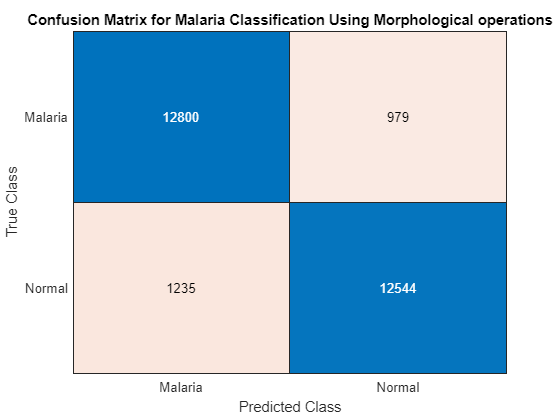

cm = confusionchart(labelsC,predsC);
%'RowSummary','row-normalized','ColumnSummary','column-normalized'
cm.Title = 'Confusion Matrix for Malaria Classification Using Morphological operations';
saveas(gcf,'confusion_mat.png')

[accuracy, sensitivity, specificity, precision, recall, f_measure, gmean] = get_metrics(labels,preds);
fprintf('Accuracy  : %.2f', accuracy*100);

Accuracy  : 91.97

fprintf('Sensitivity : %.3f', sensitivity);

Sensitivity : 0.929

fprintf('Specificity : %.3f', specificity);

Specificity : 0.910

fprintf('Precision : %.3f', precision);

Precision : 0.912

fprintf('Recall : %.3f', recall);

Recall : 0.929

fprintf('F1-Score: %.3f', f_measure );

F1-Score: 0.920